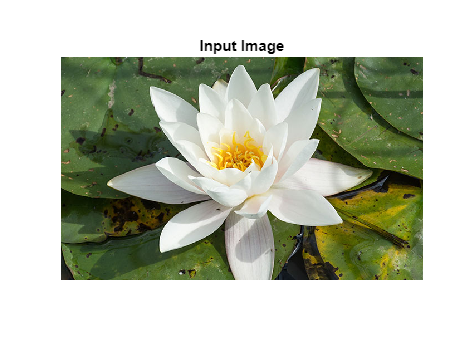

input_image = imread('flower.jpg');
input_image = uint8(input_image);
figure, imshow(input_image); title('Input Image');

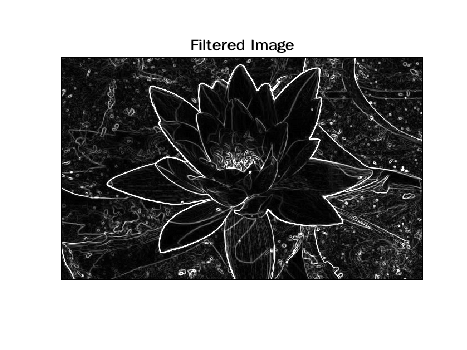

input_image = rgb2gray(input_image);
input_image = double(input_image);
filtered_image = zeros(size(input_image));
Mx = [-1 0 1; -1 0 1; -1 0 1];
My = [-1 -1 -1; 0 0 0; 1 1 1];

for i = 1:size(input_image, 1) - 2
	for j = 1:size(input_image, 2) - 2
		Gx = sum(sum(Mx.*input_image(i:i+2, j:j+2)));
		Gy = sum(sum(My.*input_image(i:i+2, j:j+2)));
				
		filtered_image(i+1, j+1) = sqrt(Gx.^2 + Gy.^2);
		
	end
end

filtered_image = uint8(filtered_image);
figure, imshow(filtered_image); title('Filtered Image');

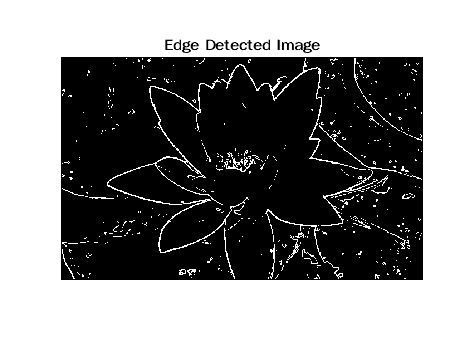


thresholdValue = 100; % varies between [0 255]
output_image = max(filtered_image, thresholdValue);
output_image(output_image == round(thresholdValue)) = 0;

output_image = im2bw(output_image);
figure, imshow(output_image); title('Edge Detected Image');

sobel = edge(input_image ,'sobel')
figure, imshow(sobel); title('Sobel');